# Proyecto Final Modelado - SIRA

## Datos del alumno

Alumnos: 

**Bejarano Lozada Elias 20213057**

**Cruz Preciado Brissa Celeste 21212149**

**Vazquez Aldeco Kennia Michelle 21212183**

Correo Institucional: **Elias.Bejarano201@tectijuana.edu.mx, L21212149@tectijuana.edu.mx,L21212183@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Carrera: **Ingeniería Biomédica**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos generales de la simulación

clc; clear all; close all;
tend = '10';
file = 'SistemaPFSIRA';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';

## Respuesta 

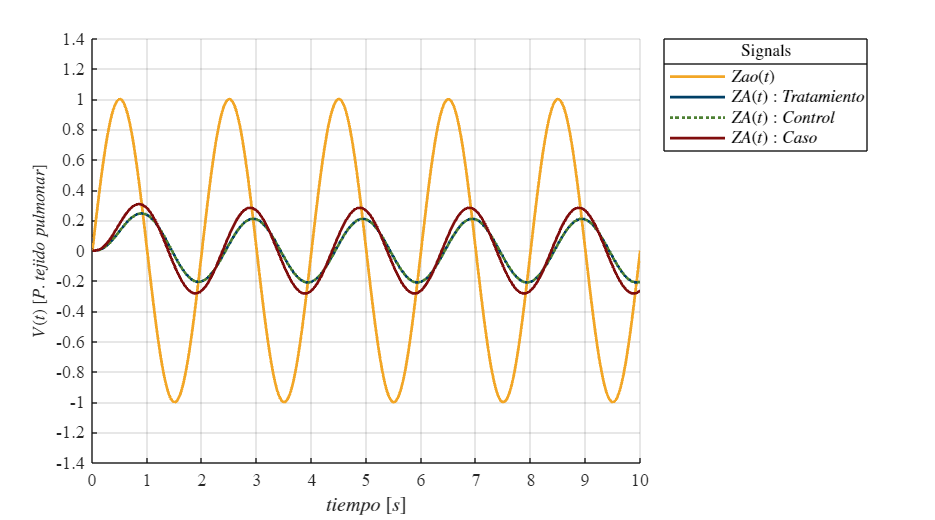

S= sim(file,parameters);
plotSignal(S.t,S.Zax,S.Zay,S.Zaz,S.Zab)

## Función:

function plotSignal(t,Zax,Zay,Zaz,Zab)
set(figure(), 'color', 'w')
set(gcf, 'units', 'centimeters', 'position',[1,5,18,10])
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
hold on; grid on

plot(t, Zax , 'LineWidth', 1.5 ,'Color',[0.95,0.65,0.15])
plot(t, Zay, 'LineWidth',1.5, 'Color',[0,0.25,0.4])
plot(t, Zaz, ':','LineWidth', 1.5 ,'Color',[0.3,0.5,0.2])
plot(t, Zab, 'LineWidth',1.5, 'Color',[0.5,0.05,0.05])

L = legend('$Zao(t)$','$ZA(t): Tratamiento$','$ZA(t): Control$','$ZA(t): Caso$');
set(L,'Interpreter','Latex', 'FontSize', 9, 'Location','NorthEastOutside')
title(L,'Signals')

xlabel('$tiempo$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$V(t)$ $[P.$ $tejido$ $pulmonar]$','Interpreter','Latex','FontSize',9)
 
xlim([0,10]); xticks (0:1:10)
ylim([-1.4,1.4]); yticks(-1.4:0.2:1.4)
name = 'ProyectoFinalModelado.pdf';
exportgraphics(gcf,name,'ContentType','vector')
end
